The kernel super class allows addition subtraction multiplication and division.

A kernel can then be made periodic in a given dimension or set of dimensions with an enforced period.

A kernel matrix can then be constructed using the build method of a kernel.

clear all
close all
clc

xx = lhsdesign(100,2);

a = kernels.EQ_special(3,1)

a =   EQ_special with properties:

         theta: 1
       kernels: {[1×1 kernels.EQ_special]}
    operations: []
       warping: {[1×1 struct]}
        thetas: {[1]}
        scales: {[3]}
         scale: [3]
             w: [1×1 struct]
         signn: [0]
             X: []



[K, dK] = a.build(xx,xx);

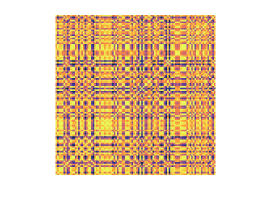


figure
pcolor(K)
shading flat
axis off
axis square
utils.cmocean('thermal')

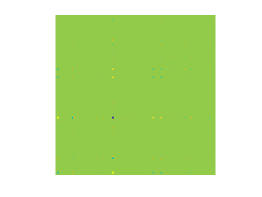

figure
pcolor(pinv(K))
shading flat
axis off
axis square

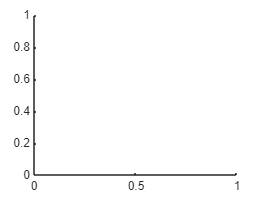

Z = GP([],a);
x1 = lhsdesign(100,2);

figure
hold on

for i = 1:30
    ysamp = Z.samplePrior(x1);
    plot3(x1(:,1),x1(:,2),ysamp,'.')
end

Error using mvnrnd (line 115)
SIGMA must be a positive semi-definite matrix.

Error in GP/samplePrior (line 101)
            y = mvnrnd(0*x(:,1),K);